## cse327hw9

Zian Shang

###     Notes: 

        Problem not solved: There are bugs with either normalized patches or matched corners of src and dest images, resulting the H matrix to be incorrect. 

% Read images
src = double(rgb2gray(imread("Image1.jpg")));
dest = double(rgb2gray(imread("Image2.jpg")));

% imshowpair(uint8(src), uint8(dest), "montage");

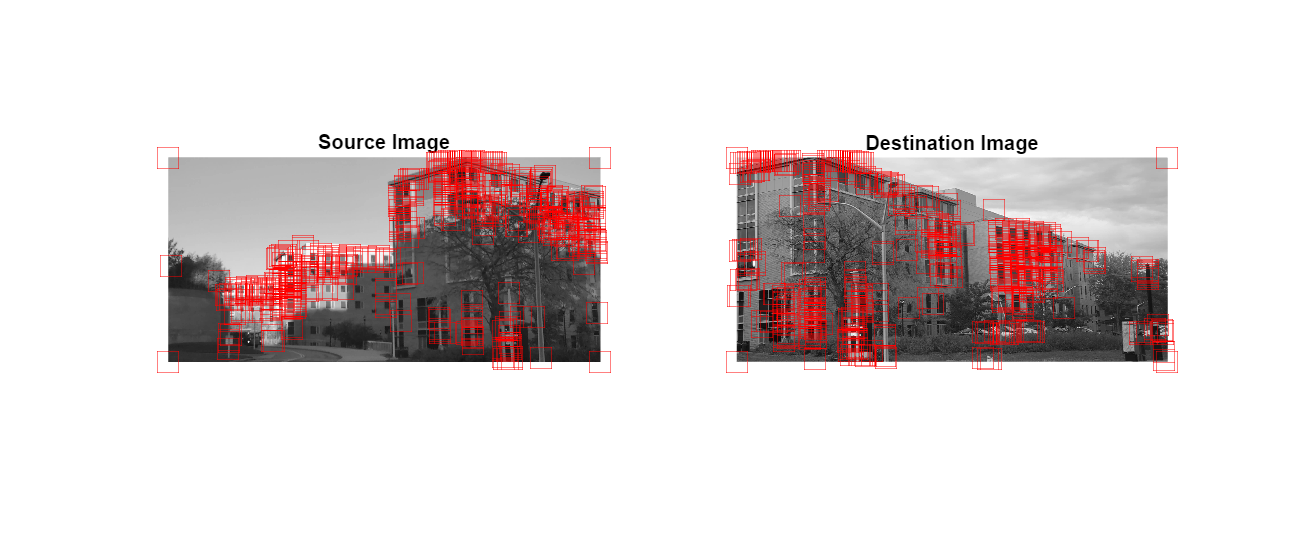

% Detect corners in src and dest images
Sigma = 15;
N = 5;
D = 10;
M = 500;
[corners_src, r_src] = detectHarrisCorners(src, Sigma, N, D, M);
[corners_dest, r_dest] = detectHarrisCorners(dest, Sigma, N, D, M);

% Display both figures with corners
% Create a new figure with larger size
figure('Position', [100, 100, 1200, 500]);

% subplot 1
subplot(1, 2, 1);
imshow(uint8(src));
hold on;
plot(corners_src(:, 2), corners_src(:, 1), 'rsquare', 'MarkerSize', 15);
title('Source Image');
hold off;

% subplot 2
subplot(1, 2, 2);
imshow(uint8(dest));
hold on;
plot(corners_dest(:, 2), corners_dest(:, 1), 'rsquare', 'MarkerSize', 15);
title('Destination Image');
hold off;

% Extract intensity patches around corners
patches_src = extractPatches(src, corners_src, 4);
patches_dest = extractPatches(dest, corners_dest, 4);

% Normalize patches 
normalized_patches_src = normalizePatches(patches_src);
normalized_patches_dest = normalizePatches(patches_dest);
% disp(normalized_patches_src);
% disp(normalized_patches_dest);

% Calculate NCC score
NCC_score = transpose(normalized_patches_src)*normalized_patches_dest;
disp(NCC_score);

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

% Look for matched corners using NCC score

% Set thresholds for matching based on NCC
rowThreshold = 0.9;
colThreshold = 0.9;

% Initialize matrices to store matched points
matchedSrcPoints = zeros(0, 2);
matchedDestPoints = zeros(0, 2);

% Initialize an array to track already matched corners in the destination image
alreadyMatchedDest = false(1, size(corners_dest, 1));

% Iterate through each corner in the source image
for i = 1:size(corners_src, 1)
    % Get the row and column corresponding to the current source corner in NCC_score
    nccScoresRow = NCC_score(i, :);
    nccScoresCol = NCC_score(:, i);
    
    % Find the index of the destination corner with the max NCC score along rows
    [maxRowNCC, bestMatchIndexRow] = max(nccScoresRow);
    
    % Find the index of the destination corner with the maximum NCC score along columns
    [maxColNCC, bestMatchIndexCol] = max(nccScoresCol);
    
    % Check if the best match along rows meets the threshold
    if maxRowNCC > rowThreshold && maxRowNCC > nccScoresCol(bestMatchIndexRow) && ~alreadyMatchedDest(bestMatchIndexRow)
        % Add the matched points to the matrices
        matchedSrcPoints = [matchedSrcPoints; corners_src(i, :)];
        matchedDestPoints = [matchedDestPoints; corners_dest(bestMatchIndexRow, :)];
        alreadyMatchedDest(bestMatchIndexRow) = true;
    end
    
    % Check if the best match along columns meets the threshold
    if maxColNCC > colThreshold && maxColNCC > nccScoresRow(bestMatchIndexCol) && ~alreadyMatchedDest(i)
        % Add the matched points to the matrices
        matchedSrcPoints = [matchedSrcPoints; corners_src(bestMatchIndexCol, :)];
        matchedDestPoints = [matchedDestPoints; corners_dest(i, :)];
        alreadyMatchedDest(i) = true;
    end
end

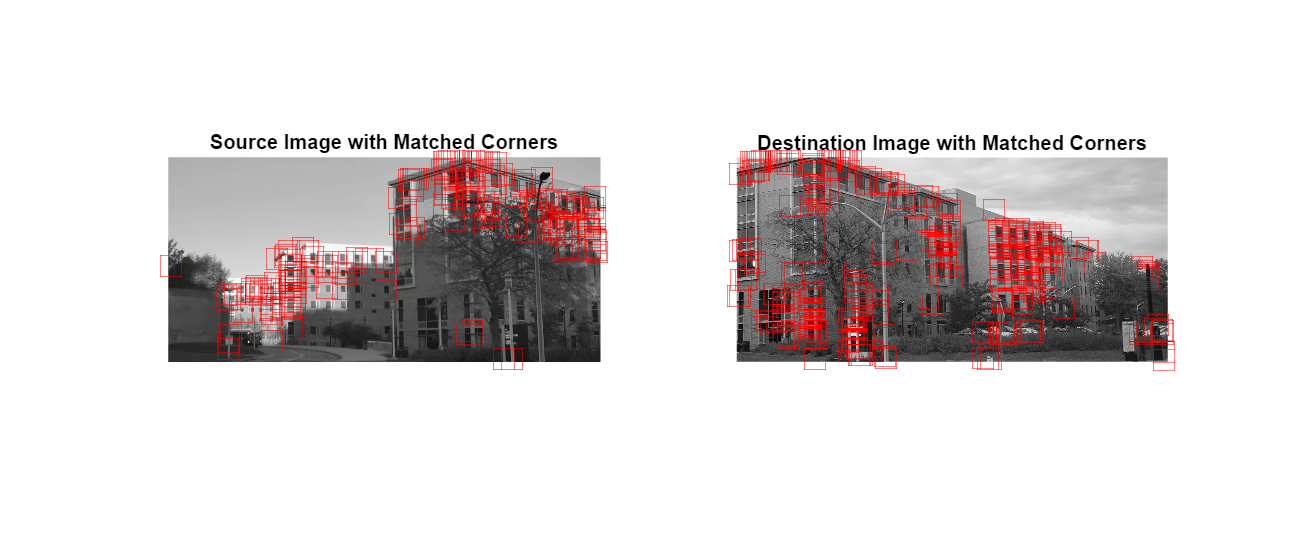

% Visualize the matched corners on the images
figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
imshow(uint8(src));
hold on;
plot(matchedSrcPoints(:, 2), matchedSrcPoints(:, 1), 'rsquare', 'MarkerSize', 15);
title('Source Image with Matched Corners');

subplot(1, 2, 2);
imshow(uint8(dest));
hold on;
plot(matchedDestPoints(:, 2), matchedDestPoints(:, 1), 'rsquare', 'MarkerSize', 15);
title('Destination Image with Matched Corners');

% Set the RANSAC parameters
inlierDistanceThreshold = 5;

% Initialize variables
bestH = [];
maxInlierCount = 0;

% Perform RANSAC
for iteration = 1:1000
    % Randomly sample four pairs of points
    sampleIndices = randperm(size(matchedSrcPoints, 1), 4);
    sampleSrcPoints = matchedSrcPoints(sampleIndices, :);
    sampleDestPoints = matchedDestPoints(sampleIndices, :);

     % Construct the matrix A for the homography estimation
    A = zeros(8, 9);
    for i = 1:4
        A(2*i-1, :) = [sampleSrcPoints(i, 1), sampleSrcPoints(i, 2), 1, 0, 0, 0, -sampleSrcPoints(i, 1) * sampleDestPoints(i, 1), -sampleSrcPoints(i, 2) * sampleDestPoints(i, 1), -sampleDestPoints(i, 1)];
        A(2*i, :) = [0, 0, 0, sampleSrcPoints(i, 1), sampleSrcPoints(i, 2), 1, -sampleSrcPoints(i, 1) * sampleDestPoints(i, 2), -sampleSrcPoints(i, 2) * sampleDestPoints(i, 2), -sampleDestPoints(i, 2)];
    end

     % Extract the homography matrix H from the last column of V using vsd
    [U, S, V] = svd(A);
    H = reshape(V(:, end), 3,3)';
    H = H / H(3, 3);

    % Compute warped source corners
    warped_corners_src = computeWarpedCorners(H, matchedSrcPoints);

    distances = sqrt(sum((warped_corners_src - matchedDestPoints).^2, 2));
    inlierIndices = distances < inlierDistanceThreshold;
    inlierCount = sum(inlierIndices);

    % Update the bestH if the current one has more inliers
    if inlierCount > maxInlierCount
        bestH = H;
        maxInlierCount = inlierCount;
    end
end
% bestH = bestH / bestH(3, 3);
disp(bestH);

   -0.4081   -0.0711  146.1009
   -1.3579   -0.4690  931.5268
   -0.0012   -0.0005    1.0000



disp(maxInlierCount);

     5



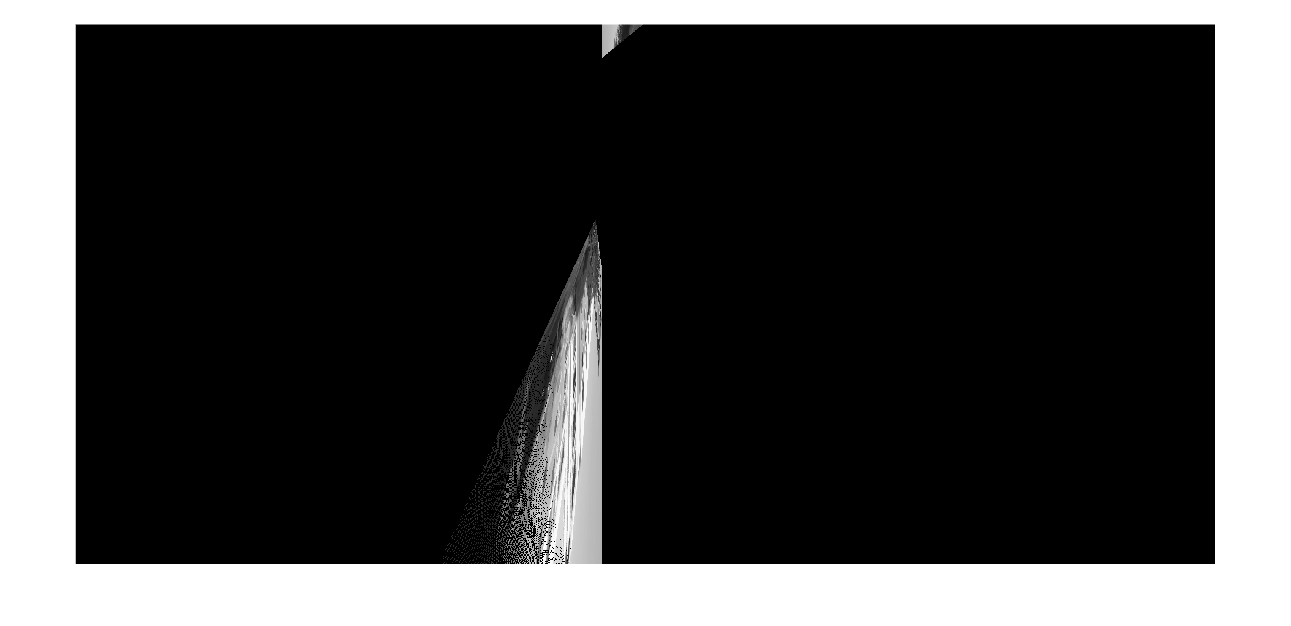

% Forward warping using the nearest neighbor

[n_rows_src, n_cols_src] = size(src);
[n_rows_dest, n_cols_dest] = size(dest);

% Initialize warped img
warpedImgForward = zeros(n_rows_src, n_cols_src);

for x = 1:n_cols_src
    for y= 1:n_rows_src

            p = [x;y;1];
            p_prime = H * p;
            x_prime = p_prime(1)/p_prime(3);
            y_prime = p_prime(2)/p_prime(3);

            % Check if the new position is out of boundary, if so, continue
            if x_prime<1 || x_prime>n_cols_dest || y_prime<1 || y_prime>n_rows_dest
                continue;
            end
            % Insert src density to warpted img
            warpedImgForward(round(y_prime), round(x_prime)) = src(y, x);
    end
end
figure;
imshow(uint8(warpedImgForward));

function [corners, R] = detectHarrisCorners(Image, Sigma, N, D, M)
    % perform guassian filtering
    Ismoothed = gua_filtering(Image,Sigma);

    % Compute gradient images Gx, Gy
    kernelx = [-1 0 1];
    kernely = [-1; 0; 1];
    Gx = imfilter(Ismoothed, kernelx, "conv");
    Gy = imfilter(Ismoothed, kernely, "conv");

    % Compute products of derivatives
    Gx2 = Gx.^2;
    Gy2 = Gy.^2;
    Gxy = Gx.*Gy;

    % Compute sums of products over local N*N neighborhood
    box_filter = ones(N);

    Sx2 = imfilter(Gx2, box_filter); % M11
    Sy2 = imfilter(Gy2, box_filter); % M22
    Sxy = imfilter(Gxy, box_filter); % M12 or M21

    % Compute R value
    k=0.05;
    R = (Sx2.*Sy2-Sxy.^2)-k*(Sx2+Sy2).^2;

    Rcopy = R;

    % find the first corner position
    maxValue = max(max(Rcopy));
    [maxX, maxY] = find(Rcopy == maxValue);
    corners = [maxX maxY];

    % Loop M-1 times to find the rest corners
    for i = 2:M
        % mask neiboring positions of the previous corner
        Rcopy = mask(Rcopy, maxX, maxY, D);

        % look for next max position
        maxValue = max(max(Rcopy));
        [maxX, maxY] = find(Rcopy == maxValue);
        corners = [corners; maxX maxY];
    end 
end

% Function to extract patches
function patches = extractPatches(image, corners, patchSize)
    numCorners = size(corners, 1);
    patches = zeros(patchSize, patchSize, numCorners);
    
    halfPatchSize = floor(patchSize / 2);
    
    for i = 1:numCorners
        row = corners(i, 1);
        col = corners(i, 2);
        
        % Calculate patch boundaries
        rowStart = max(1, row - halfPatchSize);
        rowEnd = min(size(image, 1), row + halfPatchSize);
        colStart = max(1, col - halfPatchSize);
        colEnd = min(size(image, 2), col + halfPatchSize);
        
        % Adjust patch size if it hits the boundaries
        actualPatchSize = [rowEnd - rowStart + 1, colEnd - colStart + 1];
        
        % Extract the patch
        patches(1:actualPatchSize(1), 1:actualPatchSize(2), i) = ... 
            image(rowStart:rowEnd, colStart:colEnd);
    end
end

% Function to convert 3D patches to 2D and normalize
function normalized_patches = normalizePatches(patches)
    % Reshape patches to a 2D matrix
    patches = reshape(patches, [], size(patches, 3));

    mean_values = mean(patches, 1);
    std_values = std(patches, 1);

    % Duplicate mean and std
    mean_matrix = repmat(mean_values, size(patches, 1), 1);
    std_matrix = repmat(std_values, size(patches, 1), 1);

    normalized_patches = (patches - mean_matrix) ./ std_matrix;
end

% Function to compute warped source corners
function warped_corners = computeWarpedCorners(H, src_points)
    warped_corners = zeros(size(src_points));

    for i = 1:size(src_points, 1)
        % Convert homogeneous coordinates
        homogeneous_coords = [src_points(i, :) 1]';
        
        % Apply homography transformation
        transformed_coords = H * homogeneous_coords;
        transformed_coords = transformed_coords / transformed_coords(3);
        
        % Store the transformed coordinates
        warped_corners(i, :) = transformed_coords(1:2)';
    end
end

% Function to perform guassian filtering for harris corner detection
function guaF=gua_filtering(Image, Sigma)
    halfwid=3*Sigma;
    [xx, yy] = meshgrid(-halfwid:halfwid,-halfwid:halfwid);     % create meshgrid

    Gs=exp(-1/(2*Sigma^2) * (xx.^2 +yy.^2)) / (2*pi*Sigma^2);   % calculate Guassian space kernel

    guaF=imfilter(Image, Gs);                                    % apply Guassian kernel to input image, default zero-padding
end

% Function to mask neighboring position of a corner for harris corner
% detection
function R = mask(R, maxX, maxY, D)
    % Obtain start and end positions
    Xstart = max(1, maxX-D);
    Xend = min(size(R, 1), maxX+D);
    Ystart = max(1, maxY-D);
    Yend = min(size(R, 2), maxY+D);

    % Set the values in the neighborhood to -inf
    for i = Xstart : Xend
        for j = Ystart : Yend
            R(i, j) = -inf;
        end
    end
end